clear;
n=2;
tcoordinate=sym("u%d",[n,1]);
coordinate=[tcoordinate(1)*cos(tcoordinate(2))
    tcoordinate(1)*sin(tcoordinate(2))];

M=coordinate(1)^2+coordinate(2)^2;
X=simplify([ 2*coordinate(1)/(1+M)
    2*coordinate(2)/(1+M)
    (M-1)/(M+1)]);
uinterval=[0 5];
vinterval=[0 2*pi];
hh=differential_geometry("n",n,"coordinate",tcoordinate,"X",X);

hh();
hh.g

$$ans = \left(\begin{array}{cc} \frac{4}{{\left({u_{1}}^{2}+1\right)}^{2}} & 0\\ 0 & \frac{4\,{u_{1}}^{2}}{{\left({u_{1}}^{2}+1\right)}^{2}} \end{array}\right)$$

hh.connection

$$\left(\begin{array}{cc} -\frac{2\,u_{1}}{{u_{1}}^{2}+1} & 0\\ 0 & \frac{{\left({u_{1}}^{2}+1\right)}^{2}\,\left(\frac{8\,u_{1}}{{\left({u_{1}}^{2}+1\right)}^{2}}-\frac{16\,{u_{1}}^{3}}{{\left({u_{1}}^{2}+1\right)}^{3}}\right)}{8\,{u_{1}}^{2}} \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cc} 0 & -\frac{\sigma_{1}}{8}\\ \frac{\sigma_{1}}{8\,{u_{1}}^{2}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left({u_{1}}^{2}+1\right)}^{2}\,\left(\frac{8\,u_{1}}{{\left({u_{1}}^{2}+1\right)}^{2}}-\frac{16\,{u_{1}}^{3}}{{\left({u_{1}}^{2}+1\right)}^{3}}\right) \end{array}$$

hh.curvature_tensor();
hh.Scalar_curvature

$$ans = 2$$

hh.Gauss_curvature

$$ans = 1$$

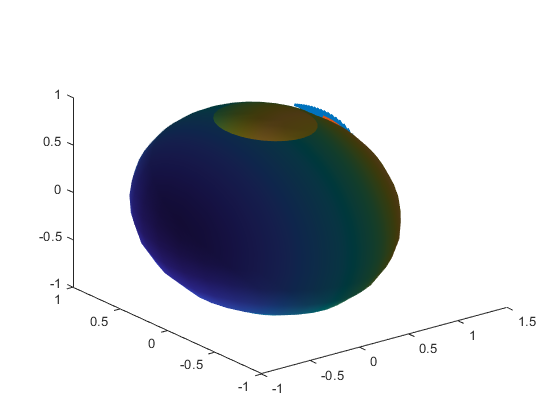

hh.drawmesh(uinterval,vinterval,0);
hold on;
syms t;
u(t)=[0.1+t;0];
% hh.scale=0;
hh.parallel_transport(u,[0;3],[1,1],30);

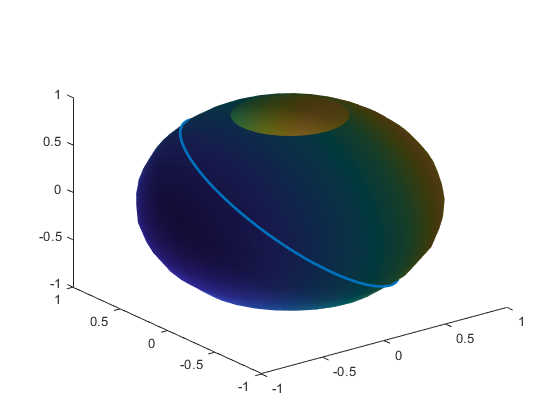

figure;
hh.drawmesh(uinterval,vinterval,0);
hold on;
hh.geodesic([0,40],[0.1, 0.1, 1, 1],100);